discreteDirac = @(n) (n==0);
stepfunction = @(n) (n>=0);
RampFunction = @(n) ((n>=0).*n);

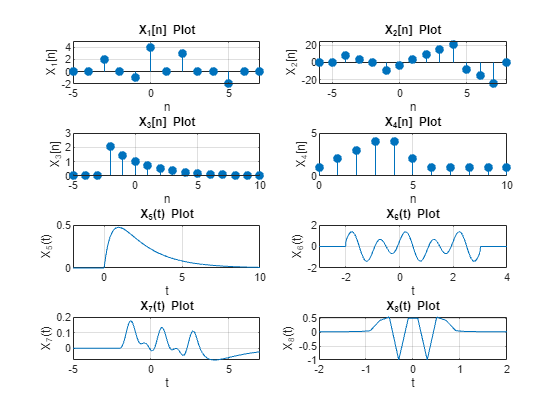

figure('Name',"Section 1.1");

%=================Plot x_1[n]====================
subplot(4,2,1);
n = -5:7;


X1 = 2*discreteDirac(n + 3) - discreteDirac(n + 1) + 4*discreteDirac(n) + 3*discreteDirac(n - 2) - 2*discreteDirac(n - 5);
stem(n,X1 , 'filled');
xlabel('n'); ylabel('X_1[n]');title("X_1[n] Plot");grid('on');xlim([-5,7]);

%=================X_2[n]==========================
subplot(4,2,2);
m = -4:4;
n = -6:8;
X2 = zeros(size(n));
for k=1:length(n)
    for i=1:length(m)
        X2(k) = X2(k) + (m(i)^2 + 2*m(i))*(discreteDirac(n(k) - m(i)) - discreteDirac(n(k) - m(i) - 3));
    end
end
stem(n,X2 , 'filled');
xlabel('n'); ylabel('X_2[n]');title("X_2[n] Plot");grid('on');xlim([-6,8]);ylim([-25,25]);

%======================X_3[n] ========================
subplot(4,2,3);
n = -5:10;
X3 = zeros(size(n));

for k = 1:length(n)
    X3(k) = (0.7).^n(k)*stepfunction(n(k) + 2) - (-0.4).^n(k).*(stepfunction(n(k)-3) - stepfunction(n(k)-9));
end
stem(n,X3 , 'filled');
xlabel('n'); ylabel('X_3[n]');title("X_3[n] Plot");grid('on');xlim([-5,10]);ylim([0,3])

%======================X_4[n] ========================
subplot(4,2,4);
n = -0:10;
X4 = RampFunction(n+1) -2.*RampFunction(n-3) + RampFunction(n-6) + discreteDirac(n-4);
stem(n,X4 , 'filled');
xlabel('n'); ylabel('X_4[n]');title("X_4[n] Plot");grid('on');xlim([0,10]);ylim([0,5])
%======================X_5(t) ========================
subplot(4,2,5);
t = linspace(-10,10,1000);
X5 = (exp(-0.5.*t) - exp(-2.*t)).*stepfunction(t);
plot(t , X5);
xlabel('t'); ylabel('X_5(t)');title("X_5(t) Plot");grid('on');xlim([-2,10]);
%======================X_6(t) ========================
subplot(4,2,6);
t = linspace(-10,10,1000);
X6 = (sin(2.*pi.*t) + 0.5.*cos(pi.*t)).*(stepfunction(t+2) -stepfunction(t-3));
plot(t , X6);
xlabel('t'); ylabel('X_6(t)');title("X_6(t) Plot");grid('on');xlim([-3,4]);
%======================X_7(t) ========================
subplot(4,2,7);
t = linspace(-20,20,1999);
X7 = conv(X6,X5)*20/1000; 
plot(t , X7);
xlabel('t'); ylabel('X_7(t)');title("X_7(t) Plot");grid('on');xlim([-5 7])
%======================X_8(t) ========================
subplot(4,2,8);
t = linspace(-10,10,100);
X8 = zeros(size(t));
for i = -8:8
    X8 = X8 + sinc(10.*t-i).*cos(pi/3.*i);
end
plot(t , X8);
xlabel('t'); ylabel('X_8(t)');title("X_8(t) Plot");grid('on');xlim([-2 2]);

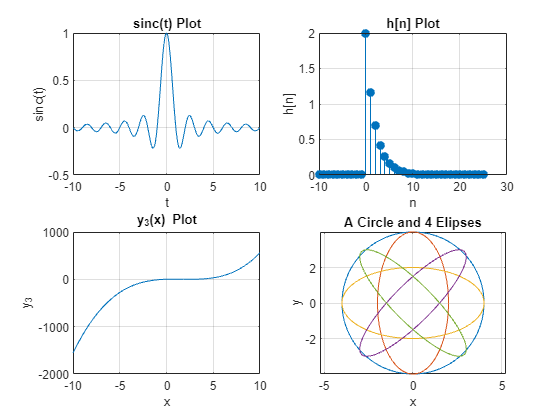

figure('Name',"Section 1.2");
dt = 1/100;
%===================sinc(t)===================
subplot(2,2,1);
t = -10:dt:10;
plot(t, sinc(t));
xlabel('t'); ylabel('sinc(t)');title("sinc(t) Plot");grid('on');
%==================h[n]==========================
subplot(2,2,2);
n = -10:25;
h = ((1/2).^n + (2/3).^n).*stepfunction(n);
stem(n,h,'filled');
xlabel('n'); ylabel('h[n]');title("h[n] Plot");grid('on');
%====================y_3(x)================================
subplot(2,2,3);
x = -10:dt:10;
y3 = x.^3 - 5.*x.^2+6.*x + 2;
plot(x, y3);
xlabel('x'); ylabel('y_3');title("y_3(x) Plot");grid('on');
%====================Circles and Elipses==================
subplot(2,2,4);
t = 0:dt:2*pi;
plot(4.*cos(t) , 4.*sin(t));
hold on;
plot(2.*cos(t),4.*sin(t));
hold on;
plot(4.*sin(t), 2.*cos(t));
hold on; 
plot(3.*cos(t-pi/3) , 3.*sin(t))
hold on;
plot(3.*cos(t+pi/3) , 3.*sin(t))
xlabel('x'); ylabel('y');title("A Circle and 4 Elipses");grid('on');
axis('equal');

# Compare the results of written Function

x = [1 3 6 4];
y = [5 6 4 2 1 3];
myConvLoop(x,y);
myConvMatrix(x,y);
myConvFFT(x,y);
conv(x,y);

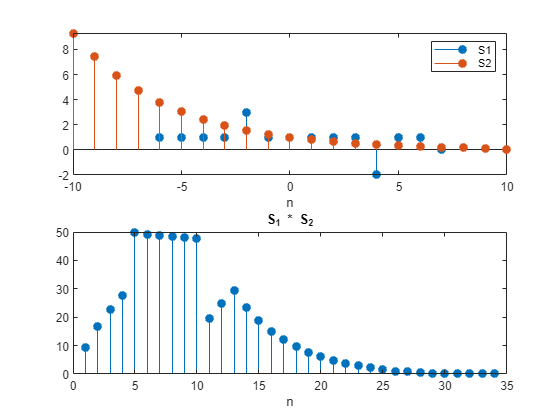

n1 = -6:7;
n2 = -10:10;
n3 = -12:13;

S1 = stepfunction(n1+6) - stepfunction(n1-7) + 2.*discreteDirac(n1+2) -3.*discreteDirac(n1-4);
S2 = (4/5).^n2 .* (stepfunction(n2+10) - stepfunction(n2-10));
S3 = n3.*cos(0.4.*n3).*(stepfunction(n3+12) - stepfunction(n3-13));

y12 = myConvFFT(S1,S2);
y13 = myConvFFT(S1,S3);
y23 = myConvFFT(S2,S3);
figure;
subplot(2,1,1);
stem(n1,S1 , 'filled');
xlabel('n');
hold on;
stem(n2,S2,'filled');
legend("S1", "S2");
subplot(2,1,2);
stem(y12,'filled');
xlabel("n");
title("S_1 * S_2")

# Time Comparasion

N = 2000;
X1 = rand(N,1)';
X2 = rand(N,1)';

tic
myConvLoop(X1,X2);
toc

Elapsed time is 0.043463 seconds.



tic
myConvMatrix(X1,X2);
toc

Elapsed time is 0.060118 seconds.



tic
myConvFFT(X1,X2);
toc

Elapsed time is 0.004139 seconds.



tic 
conv(X1,X2);
toc

Elapsed time is 0.003877 seconds.


Nvals = round(logspace(2, 4, 12));  % from 1e2 to 1e4
tLoop   = zeros(size(Nvals));
tMatrix = zeros(size(Nvals));
tFFT    = zeros(size(Nvals));
tConv   = zeros(size(Nvals));

for k = 1:length(Nvals)
    N = Nvals(k);

    X1 = rand(1, N);
    X2 = rand(1, N);

    tLoop(k) = timeit(@() myConvLoop(X1, X2));
    tMatrix(k) = timeit(@() myConvMatrix(X1, X2));
    tFFT(k) = timeit(@() myConvFFT(X1, X2));
    tConv(k) = timeit(@() conv(X1, X2));

    fprintf('N = %d done\n', N);
end

N = 100 done
N = 152 done
N = 231 done
N = 351 done
N = 534 done
N = 811 done
N = 1233 done
N = 1874 done
N = 2848 done
N = 4329 done
N = 6579 done
N = 10000 done


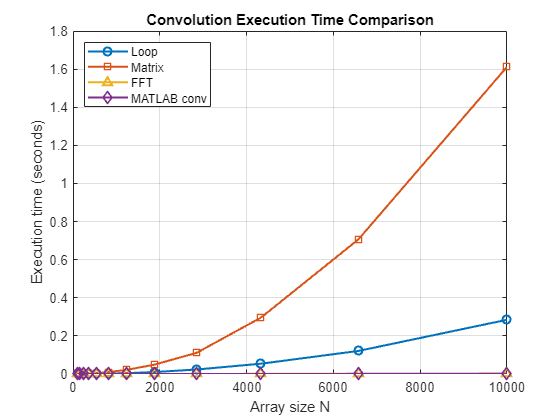


figure;
plot(Nvals, tLoop,   '-o', 'LineWidth', 1.5); hold on;
plot(Nvals, tMatrix, '-s', 'LineWidth', 1.5);
plot(Nvals, tFFT,    '-^', 'LineWidth', 1.5);
plot(Nvals, tConv,   '-d', 'LineWidth', 1.5);
grid on;

xlabel('Array size N');
ylabel('Execution time (seconds)');
legend('Matix', 'Loop', 'FFT', 'MATLAB conv', 'Location', 'northwest');
title('Convolution Execution Time Comparison');

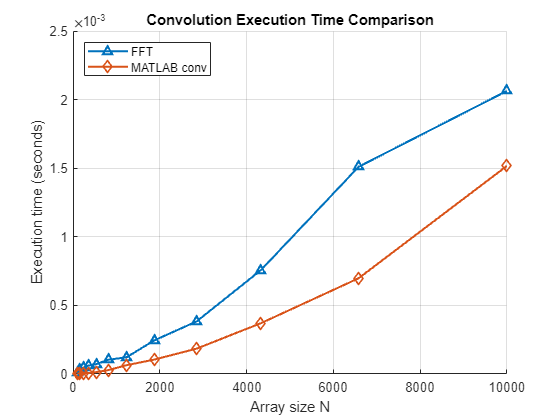

figure;
hold on;
plot(Nvals, tFFT,    '-^', 'LineWidth', 1.5);
plot(Nvals, tConv,   '-d', 'LineWidth', 1.5);
grid on;

xlabel('Array size N');
ylabel('Execution time (seconds)');
legend('FFT', 'MATLAB conv', 'Location', 'northwest');
title('Convolution Execution Time Comparison');

# Interpolation:


$$f[n] = 3 \frac{\sin\left(\frac\pi3 \cdot n\right)}{\pi n}$$


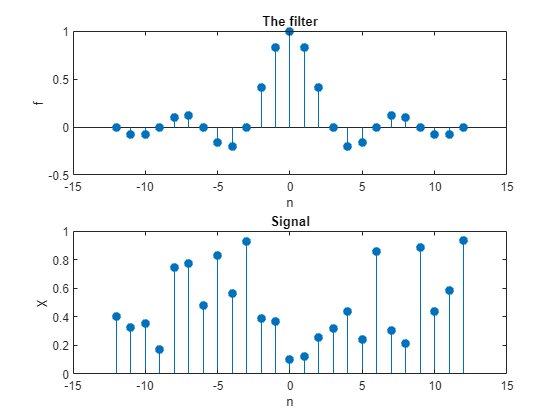

n = -12:12;
X = rand(1,25);

f = zeros(size(n));
for k = 1:length(n)
    if n(k) == 0
        f(k) = 1;  
    else
        f(k) = 3*sin(pi/3*n(k)) / (pi*n(k));
    end
end

figure;
subplot(2,1,1);
stem(n, f, 'filled'); xlabel('n'); ylabel('f'); title('The filter');
subplot(2,1,2);
stem(n, X, 'filled'); xlabel('n'); ylabel('X'); title('Signal');

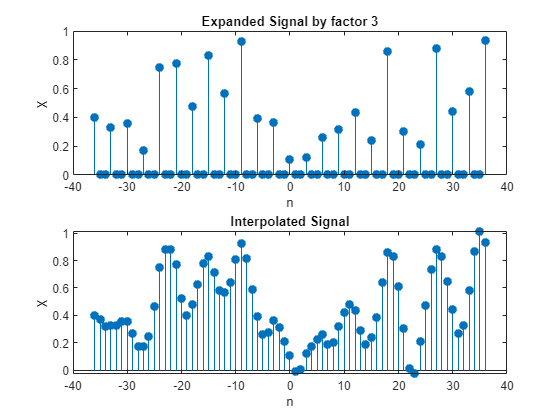


n_expanded = -36:36;
X_expanded = zeros(1, 3*length(X)-2);

for i = 0:length(X)-1
    X_expanded(3*i + 1) = X(i+1);
end

X_interpolated = conv(X_expanded, f, 'same');

figure;
subplot(2,1,1);
stem(n_expanded, X_expanded, 'filled'); xlabel('n'); ylabel('X'); title('Expanded Signal by factor 3');
subplot(2,1,2);
stem(n_expanded, X_interpolated, 'filled'); xlabel('n'); ylabel('X'); title('Interpolated Signal');

# Up scale  an Image

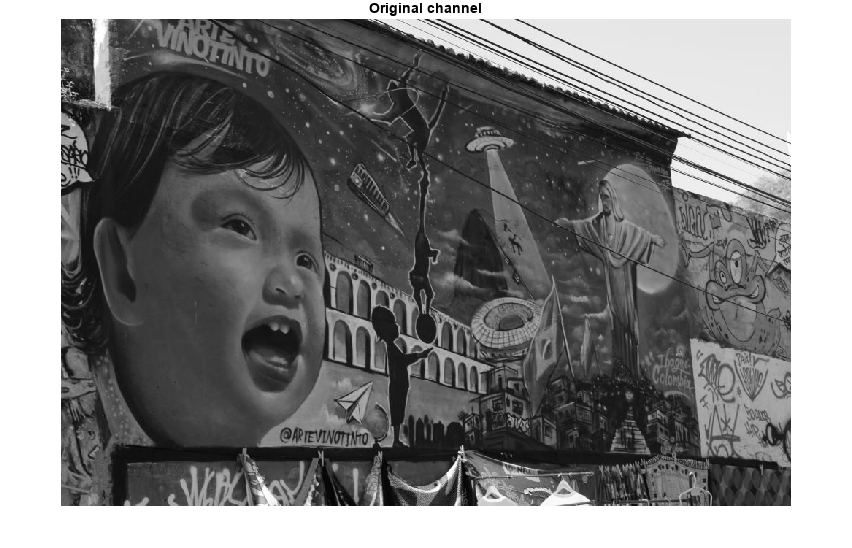

%===================================================
img = rgb2gray(imread("Image.JPG"));
y = upScaleImage3(img);
figure;
imshow(uint8(img(:,:))); 
title('Original channel');

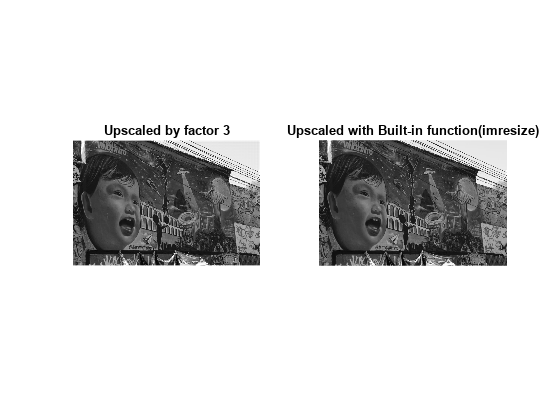

figure;
subplot(1,2,1);
imshow(uint8(y));
title('Upscaled by factor 3');

subplot(1,2,2);
imshow(uint8(imresize(img,3)));
title('Upscaled with Built-in function(imresize)')

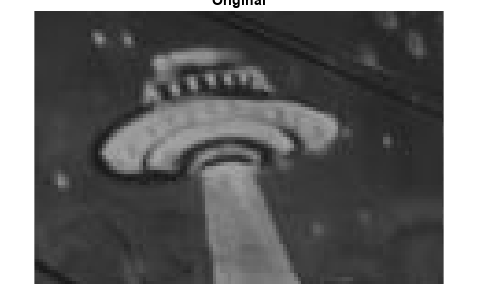

figure;
imshow(uint8(img(:,:))); 
title('Original');

xlim([538.2 649.0])
ylim([137.5 211.4])

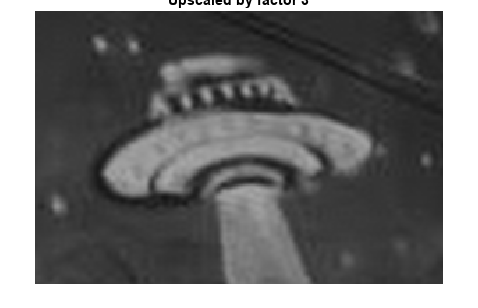


figure;
imshow(uint8(y));
title('Upscaled by factor 3');

xlim([1618 1911])
ylim([409 605])

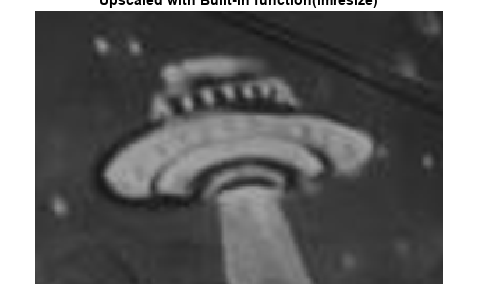


figure;
imshow(uint8(imresize(img,3)));
xlim([1618 1911])
ylim([409 605])
title('Upscaled with Built-in function(imresize)')

# Find Patterns(Identical Filter)

a = [1 -1 -1 1];
N = 50;
x = randi([0 1],1,N);
x(x==0) = -1;
insert_positions = [8 20 35]; 

for k = 1:length(insert_positions)
    idx = insert_positions(k);
    x(idx:idx+length(a)-1) = a;
end

p = fliplr(a);

y = conv(x, p);
[max_value, max_index] = max(y);

disp('Inserted positions:')

Inserted positions:


disp(insert_positions)

     8    20    35




disp('Maximum value of y[n]:')

Maximum value of y[n]:


disp(max_value)

     4




disp('Indices where maximum occurs:')

Indices where maximum occurs:


disp(find(y == max_value)-length(a))

     7    19    34




imgH = 128;
imgW = 128;
noiseProb = 0.5;                
img = rand(imgH, imgW) > noiseProb;   
img = double(img);

tmpl = [1 1 1 1 1;
        1 0 0 0 1;
        1 0 1 0 1;
        1 0 0 0 1;
        1 1 1 1 1];
tmpl = double(tmpl);

row0 = 30;
col0 = 50;

img(row0:row0+size(tmpl,1)-1, col0:col0+size(tmpl,2)-1) = tmpl;


h = rot90(tmpl, 2); %Rotate array by 2*90^\circ degree

H = zeros(size(img));
H(1:size(h,1), 1:size(h,2)) = h;

IMG = fft2(img);
HMF = conj(fft2(H));

corrMap = real(ifft2(IMG .* HMF));

[~, idx] = max(corrMap(:));
[yPeak, xPeak] = ind2sub(size(corrMap), idx);

detRow = yPeak ;
detCol = xPeak ;

fprintf('Pattern injected at: %d, %d\n', row0, col0);

Pattern injected at: 30, 50


fprintf('Pattern detected at: %d, %d\n', detRow, detCol);

Pattern detected at: 30, 50


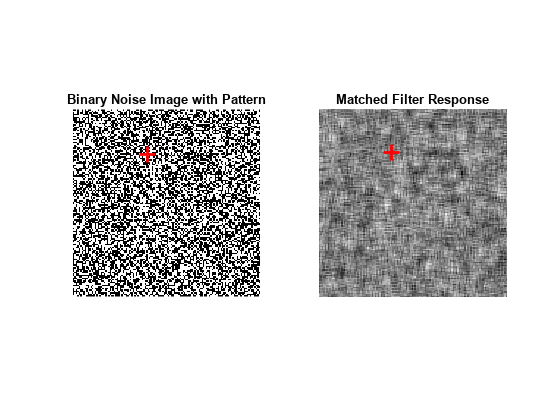


figure;

subplot(1,2,1);
imshow(img, []);
hold on;
plot(xPeak + size(tmpl,1)/2-1, yPeak + size(tmpl,2)/2-1, 'r+', 'MarkerSize', 12, 'LineWidth', 2);
title('Binary Noise Image with Pattern');

%subplot(1,3,2);
%imshow(tmpl, []);
%title('Template Pattern');

subplot(1,2,2);
imshow(corrMap, []);
title('Matched Filter Response');
hold on;
plot(xPeak, yPeak, 'r+', 'MarkerSize', 12, 'LineWidth', 2);
hold off;

# Image Processing

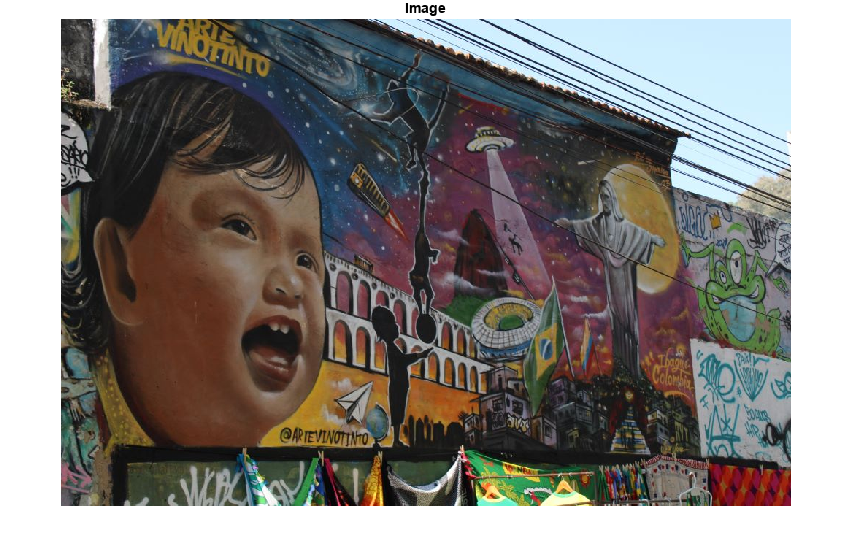

img = imread("Image.JPG");
figure;
imshow(img);
title("Image");

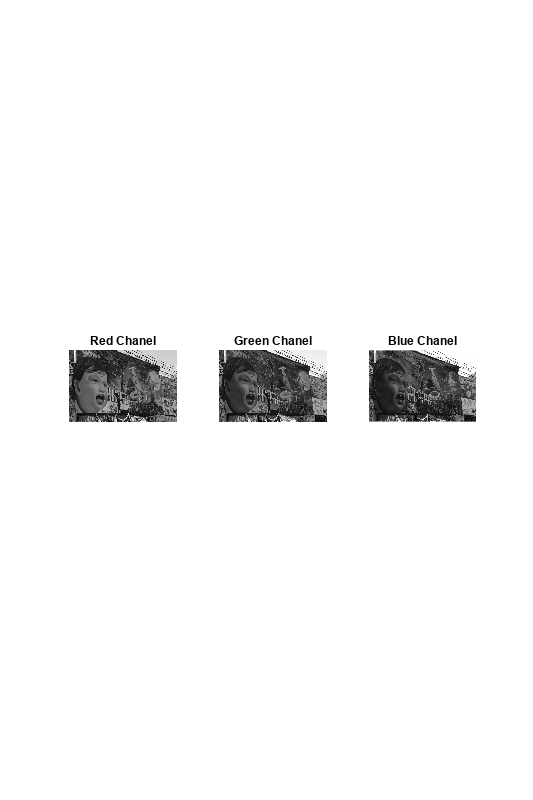


f=figure;
f.Position(3:4) = [1000 1500];
subplot(1,3,1);
imshow(img(:,:,1));
title("Red Chanel");

subplot(1,3,2);
imshow(img(:,:,2));
title("Green Chanel");

subplot(1,3,3);
imshow(img(:,:,3));
title("Blue Chanel");

## Gray Chanel

### a)Averaging the channels

grayImg = 1/3.*img(:,:,1)+1/3.*img(:,:,2)+1/3.*img(:,:,3);
f=figure;
subplot(1,2,1);
imshow(grayImg);
title("gray image:Average");

### b) Using Built-in function

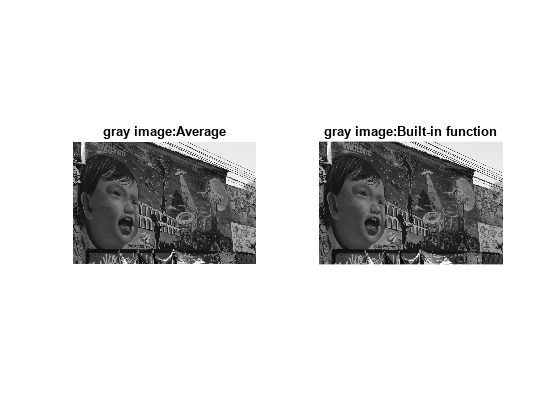

grayImg2 = rgb2gray(img);
subplot(1,2,2);
imshow(grayImg2);
title("gray image:Built-in function");

## Image Binarizing

Creates a binary image from 2-D or 3-D grayscale image `img` by replacing all values above a globally determined threshold with `1`s and setting all other values to `0`s. By default, `imbinarize` uses ***Otsu***'s method, which chooses the threshold value to minimize the intraclass variance of the thresholded black and white pixels

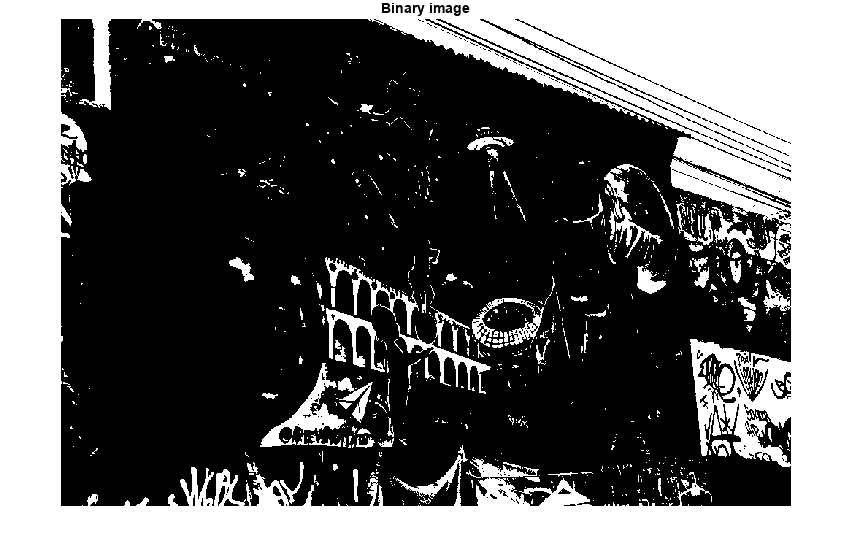

binaryImg = imbinarize(grayImg2);
figure;
subplot(1,1,1);
imshow(binaryImg);
title("Binary image");

## Sobel Operator

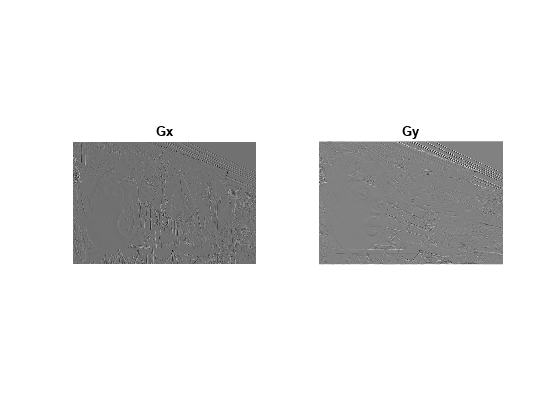

Fx = [-1 0 1;-2 0 2;-1 0 1];
Fy = [-1 -2 -1;0 0 0; 1 2 1];

Gx = conv2(grayImg, Fx,'same');
Gy = conv2(grayImg, Fy, 'same');

figure;
subplot(1,2,1);
imshow(mat2gray(Gx));
title("Gx");

subplot(1,2,2);
imshow(mat2gray(Gy));
title("Gy");

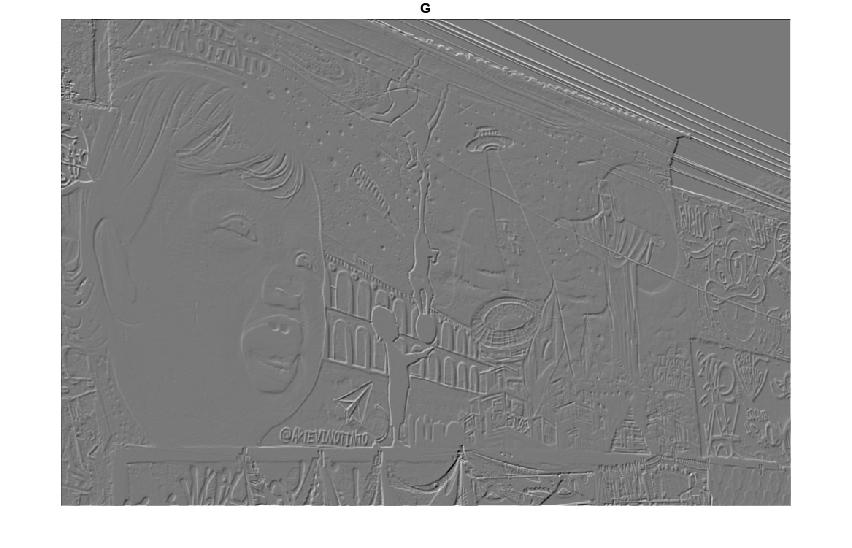

maxGx = max(Gx(:));
minGx = min(Gx(:));
maxGy = max(Gy(:));
minGy = min(Gy(:));
Gx_normal = (Gx-minGx);
Gy_normal = (Gy-minGy);
G = (Gx_normal.^2 + Gy_normal.^2).^(0.5);
figure;
subplot(1,1,1);
GNormalized = mat2gray(G); 
imshow(GNormalized);
title("G");

# Image Segmentation

## a) K-mean

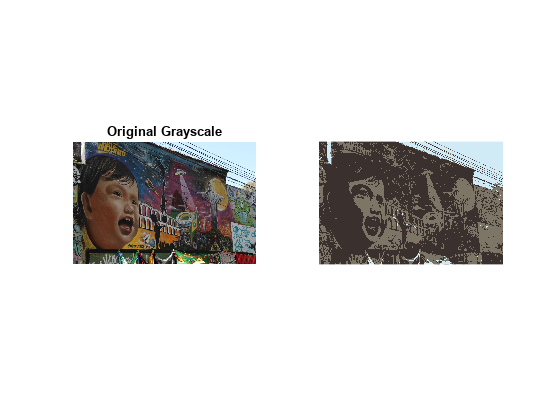

k = 3; 


initialCenters = [255, 0, 0; 0, 255, 0; 0, 0, 255]; 

result = segmentImage(img, k, initialCenters);

imshow(result);

## b)Otsu

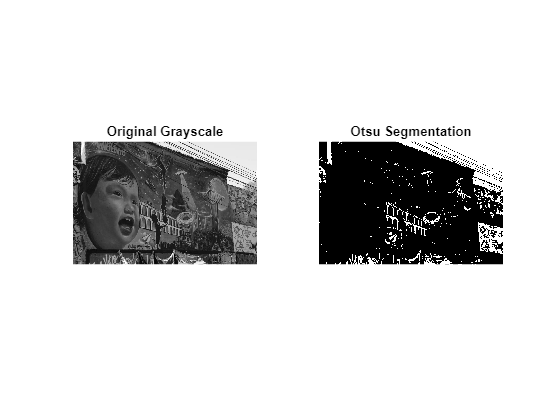

binImg = otsu_segmentation(grayImg);

figure;
subplot(1,2,1);
imshow(grayImg); 
title('Original Grayscale');

subplot(1,2,2);

imshow(binImg); 
title('Otsu Segmentation');

# Voting Simulation

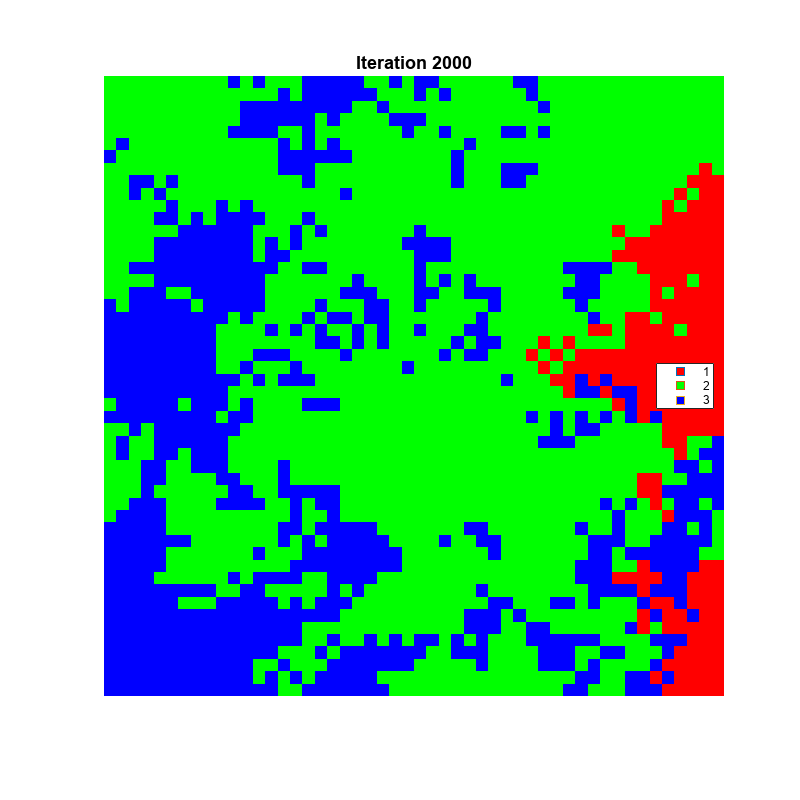

n = 50;
k = 4;

voting_simulation(n , k)

function h = myConvLoop(x , y)
    n = length(x);
    m = length(y);
    z = zeros(m+n,1);
    for i=1:n+m
        for j=max([1 i-m]):min([n i-1])
            z(i)= z(i)+ x(j).*y(i-j);
        end
    end
    h = z(2:n+m)';
end

function y = myConvMatrix(x, h)
    Nx = length(x);
    first_col = [h'; zeros(Nx-1,1)];
    first_row = [h(1); zeros(Nx-1,1)];
    H = toeplitz(first_col, first_row);

    y = (H * x')';
end

function y = myConvFFT(x , h)
    N = length(x) + length(h) -1;
    y = ifft(fft(x,N).*fft(h,N));
end

function y = upScale3_1D(x , n)
    f = zeros(size(n));
    for k = 1:length(n)
        if n(k) == 0
            f(k) = 1;  
        else
            f(k) = 3*sin(pi/3*n(k)) / (pi*n(k));
        end
    end

    X_expanded = zeros(1, 3*length(x)-2);
    
    for i = 0:length(x)-1
        X_expanded(3*i + 1) = x(i+1);
    end
    
    y = conv(X_expanded, f, 'same');
end

function y2D = upScaleImage3(img)
    img = double(img);

    if ndims(img) == 3
        img = img(:,:,1);
    end
    n = -470:470;

    [rows, cols] = size(img);
    temp = zeros(rows, 3*cols - 2);

    for r = 1:rows
        temp(r, :) = upScale3_1D(img(r, :), n);
    end
    [rows2, cols2] = size(temp);
    y2D = zeros(3*rows2 - 2, cols2);

    for c = 1:cols2
        y2D(:, c) = upScale3_1D(temp(:, c).', n).';
    end
end


function segmentedImage = segmentImage(img, k, initialCenters)

    img = double(img);
    [rows, cols, channels] = size(img);
    
    pixelList = reshape(img, rows * cols, channels);
    
    centers = initialCenters;
    
    for iter = 1:100
        oldCenters = centers;
        
        distances = pdist2(pixelList, centers);
        
        [~, labels] = min(distances, [], 2);
        
        for i = 1:k
            if sum(labels == i) > 0
                centers(i, :) = mean(pixelList(labels == i, :), 1);
            end
        end
        
        if norm(centers - oldCenters) < 0.1
            break;
        end
    end
    
    segmentedPixelList = centers(labels, :);
    segmentedImage = reshape(segmentedPixelList, rows, cols, channels);
    
    segmentedImage = uint8(segmentedImage);
end

function binaryImage = otsu_segmentation(grayImage)

    grayImage = double(grayImage);
    
    [counts, ~] = imhist(uint8(grayImage));
    
    numPixels = numel(grayImage);
    probs = counts / numPixels;
    
    cumSum = cumsum(probs);
    cumMean = cumsum((0:255)' .* probs);
    globalMean = cumMean(end);
    

    omega1 = cumSum;
    omega2 = 1 - omega1;
    
    mu1 = cumMean ./ (omega1 + eps);
    mu2 = (globalMean - cumMean) ./ (omega2 + eps);
    
    betweenClassVariance = omega1 .* omega2 .* (mu1 - mu2).^2;
    
    [~, thresholdIndex] = max(betweenClassVariance);
    threshold = (thresholdIndex - 1) / 255; 
    
    binaryImage = imbinarize(grayImage / 255, threshold);
end

function voting_simulation(n , k)

    num_iterations = 2000; 
    
    %Initial values
    votes = randi([1, 3], n, n);
    %For map votes to colors
    colors = [1 0 0;  
              0 1 0;    
              0 0 1];   
    
    figure('Position', [100, 100, 800, 800]);
    
    for iter = 1:num_iterations
        num_selected = round(n^2 / k);
        
        selected_indices = randperm(n^2, num_selected);
        
        for idx = 1:num_selected
            [i, j] = ind2sub([n, n], selected_indices(idx));
            
            neighbors = get_neighbors(i, j, n);
            
            if ~isempty(neighbors)
                neighbor_idx = randi(size(neighbors, 1));
                ni = neighbors(neighbor_idx, 1);
                nj = neighbors(neighbor_idx, 2);
                
                votes(ni, nj) = votes(i, j);
            end
        end
        
        if mod(iter, 10) == 1 || iter == num_iterations
            display_votes(votes, colors, iter);
            pause(0.05);
        end
    end
    
    display_votes(votes, colors, num_iterations);
end

function neighbors = get_neighbors(i, j, n)
    neighbors = [];
    
    directions = [-1, -1; -1, 0; -1, 1;
                   0, -1;         0, 1;
                   1, -1;  1, 0;  1, 1];
    
    for d = 1:size(directions, 1)
        ni = i + directions(d, 1);
        nj = j + directions(d, 2);
        
        if ni >= 1 && ni <= n && nj >= 1 && nj <= n
            neighbors = [neighbors; ni, nj];
        end
    end
end

function display_votes(votes, colors, iteration)
    [n, m] = size(votes);
    img = zeros(n, m, 3);
    
    for i = 1:n
        for j = 1:m
            img(i, j, :) = colors(votes(i, j), :);
        end
    end
    
    imshow(img, 'InitialMagnification', 'fit');
    title(sprintf('Iteration %d', iteration), 'FontSize', 14);
    
    hold on;
    h1 = plot(NaN, NaN, 's', 'MarkerFaceColor', colors(1,:), 'MarkerSize', 10);
    h2 = plot(NaN, NaN, 's', 'MarkerFaceColor', colors(2,:), 'MarkerSize', 10);
    h3 = plot(NaN, NaN, 's', 'MarkerFaceColor', colors(3,:), 'MarkerSize', 10);
    legend([h1, h2, h3], {'1','2','3'}, 'Location', 'best');
    hold off;
    
    drawnow;
end

